## Main function

Prepare Data and Input 

% Read data symbols and category range

filename = "IDX Stock Symbol Category Market Cap.xlsx";
sheetname = "Latest symbols";
symdbase = readtable (filename,"Sheet", sheetname) ;
A = readtable (filename, "Sheet", "Cap Category Range") ;
capCategRange = sortrows(A,"LB","ascend") ;
clearvars A

% Categorize symbols based on market cap
binEdge = sort (vertcat (capCategRange.LB, 10^6),1,"ascend") ;
CapCategory = discretize (symdbase.MarketCap_InRpTn, binEdge, capCategRange.CapCategory) ;
CapCategory = table (CapCategory) ;
symdbaseT = [symdbase, CapCategory] ;
clearvars symdbase 

Fetch data from yahoo, clean data and save into matfile

% Fetch data from yahoo, clean data and save into matfile
getCleanPVYahoo ;

% Save to matfile for easy access
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean");

Optimize parameters for WFA

% WFA Preparation and Parameters Settings
load("WFATradeData.mat", "priceVolumeClean")

paramSetUp


walk_i = 1

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 2

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 3

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 4

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 5

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 6

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 7

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 8

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 9

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 10

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 11

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 12

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 13

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 14

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 15

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 16

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 17

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 18

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 19

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 20

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 21

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 22

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 23

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


walk_i = 24

cap_i = 1

capCateg_i = "Lower Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 2

capCateg_i = "Lower Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 3

capCateg_i = "Lower Small Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 4

capCateg_i = "Upper Big Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 5

capCateg_i = "Upper Mid Cap"

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


cap_i = 6

capCateg_i = "Upper Small Cap"

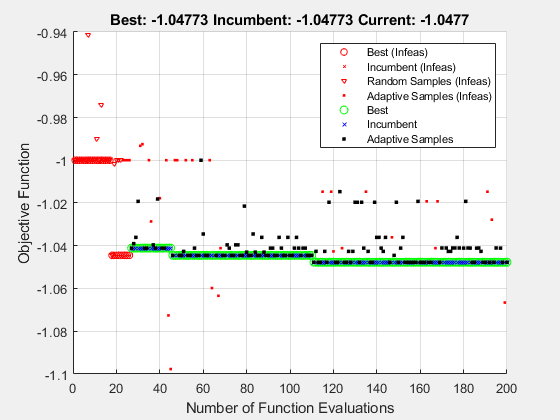

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


% Optimize parameter for each walk
tStart = tic ;
optimParamsScript ;

tStop = toc(tStart)

tStop = 1.8343e+04

% Save Opimtized parameters for WFA
load ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean")
save ("WFATradeData.mat", "priceVolumeRaw", "priceVolumeClean", "paramsStruct")


Conduct WFA on data 

WFAonData

walk_i = 1

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 1

endIdx = 5

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 1

endIdx = 5

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 1

endIdx = 5

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 1

endIdx = 5

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 1

endIdx = 5

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 1

endIdx = 5

walk_i = 2

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 6

endIdx = 10

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 6

endIdx = 10

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 6

endIdx = 10

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 6

endIdx = 10

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 6

endIdx = 10

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 6

endIdx = 10

walk_i = 3

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 11

endIdx = 15

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 11

endIdx = 15

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 11

endIdx = 15

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 11

endIdx = 15

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 11

endIdx = 15

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 11

endIdx = 15

walk_i = 4

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 16

endIdx = 20

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 16

endIdx = 20

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 16

endIdx = 20

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 16

endIdx = 20

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 16

endIdx = 20

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 16

endIdx = 20

walk_i = 5

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 21

endIdx = 25

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 21

endIdx = 25

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 21

endIdx = 25

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 21

endIdx = 25

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 21

endIdx = 25

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 21

endIdx = 25

walk_i = 6

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 26

endIdx = 30

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 26

endIdx = 30

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 26

endIdx = 30

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 26

endIdx = 30

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 26

endIdx = 30

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 26

endIdx = 30

walk_i = 7

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 31

endIdx = 35

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 31

endIdx = 35

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 31

endIdx = 35

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 31

endIdx = 35

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 31

endIdx = 35

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 31

endIdx = 35

walk_i = 8

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 36

endIdx = 40

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 36

endIdx = 40

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 36

endIdx = 40

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 36

endIdx = 40

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 36

endIdx = 40

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 36

endIdx = 40

walk_i = 9

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 41

endIdx = 45

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 41

endIdx = 45

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 41

endIdx = 45

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 41

endIdx = 45

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 41

endIdx = 45

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 41

endIdx = 45

walk_i = 10

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 46

endIdx = 50

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 46

endIdx = 50

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 46

endIdx = 50

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 46

endIdx = 50

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 46

endIdx = 50

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 46

endIdx = 50

walk_i = 11

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 51

endIdx = 55

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 51

endIdx = 55

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 51

endIdx = 55

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 51

endIdx = 55

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 51

endIdx = 55

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 51

endIdx = 55

walk_i = 12

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 56

endIdx = 60

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 56

endIdx = 60

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 56

endIdx = 60

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 56

endIdx = 60

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 56

endIdx = 60

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 56

endIdx = 60

walk_i = 13

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 61

endIdx = 65

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 61

endIdx = 65

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 61

endIdx = 65

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 61

endIdx = 65

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 61

endIdx = 65

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 61

endIdx = 65

walk_i = 14

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 66

endIdx = 70

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 66

endIdx = 70

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 66

endIdx = 70

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 66

endIdx = 70

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 66

endIdx = 70

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 66

endIdx = 70

walk_i = 15

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 71

endIdx = 75

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 71

endIdx = 75

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 71

endIdx = 75

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 71

endIdx = 75

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 71

endIdx = 75

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 71

endIdx = 75

walk_i = 16

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 76

endIdx = 80

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 76

endIdx = 80

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 76

endIdx = 80

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 76

endIdx = 80

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 76

endIdx = 80

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 76

endIdx = 80

walk_i = 17

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 81

endIdx = 85

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 81

endIdx = 85

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 81

endIdx = 85

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 81

endIdx = 85

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 81

endIdx = 85

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 81

endIdx = 85

walk_i = 18

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 86

endIdx = 90

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 86

endIdx = 90

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 86

endIdx = 90

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 86

endIdx = 90

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 86

endIdx = 90

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 86

endIdx = 90

walk_i = 19

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 91

endIdx = 95

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 91

endIdx = 95

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 91

endIdx = 95

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 91

endIdx = 95

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 91

endIdx = 95

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 91

endIdx = 95

walk_i = 20

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 96

endIdx = 100

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 96

endIdx = 100

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 96

endIdx = 100

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 96

endIdx = 100

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 96

endIdx = 100

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 96

endIdx = 100

walk_i = 21

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 101

endIdx = 105

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 101

endIdx = 105

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 101

endIdx = 105

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 101

endIdx = 105

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 101

endIdx = 105

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 101

endIdx = 105

walk_i = 22

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 106

endIdx = 110

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 106

endIdx = 110

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 106

endIdx = 110

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 106

endIdx = 110

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 106

endIdx = 110

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 106

endIdx = 110

walk_i = 23

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 111

endIdx = 115

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 111

endIdx = 115

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 111

endIdx = 115

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 111

endIdx = 115

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 111

endIdx = 115

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 111

endIdx = 115

walk_i = 24

cap_i = 1

capCateg_i = "Lower Big Cap"

startIdx = 116

endIdx = 120

cap_i = 2

capCateg_i = "Lower Mid Cap"

startIdx = 116

endIdx = 120

cap_i = 3

capCateg_i = "Lower Small Cap"

startIdx = 116

endIdx = 120

cap_i = 4

capCateg_i = "Upper Big Cap"

startIdx = 116

endIdx = 120

cap_i = 5

capCateg_i = "Upper Mid Cap"

startIdx = 116

endIdx = 120

cap_i = 6

capCateg_i = "Upper Small Cap"

startIdx = 116

endIdx = 120

Analyze the WFA results

WFAResults

walkStart_i = 1

walkEnd_i = 5

walkStart_i = 6

walkEnd_i = 10

walkStart_i = 11

walkEnd_i = 15

walkStart_i = 16

walkEnd_i = 20

walkStart_i = 21

walkEnd_i = 25

walkStart_i = 26

walkEnd_i = 30

walkStart_i = 31

walkEnd_i = 35

walkStart_i = 36

walkEnd_i = 40

walkStart_i = 41

walkEnd_i = 45

walkStart_i = 46

walkEnd_i = 50

walkStart_i = 51

walkEnd_i = 55

walkStart_i = 56

walkEnd_i = 60

walkStart_i = 61

walkEnd_i = 65

walkStart_i = 66

walkEnd_i = 70

Local functions